# Classifying Credit Card Default using Classification Learner App

Copyright (c) 2018, MathWorks, Inc.

**Goal**: To classify credit card default

**Video**: [https://www.mathworks.com/videos/machine-learning-applications-in-risk-management-classifying-credit-card-default-using-the-classification-learner-app-1536227997787.html](https://www.mathworks.com/videos/machine-learning-applications-in-risk-management-classifying-credit-card-default-using-the-classification-learner-app-1536227997787.html) 

System Requirements

- [MATLAB® R2018a](https://www.mathworks.com/products/matlab.html)

- [Statistics and Machine Learning Toolbox™](https://www.mathworks.com/products/statistics.html)

- [Paralel Computing Toolbox™](https://www.mathworks.com/products/parallel-computing.html)

**Import Data**

load creditCardDefault.mat

There are 12 variables in the dataset.

- **id**: identification number

- **creditLimit**: amount of credit limit in currency

- **gender**: 0 = female, 1 = male

- **edu**: 1 = master or PhD, 2 = bachelor, 3 = high school, 4 = less than high school

- **age**: age of customer in year

- **nDelay**: number of payment delays (months)

- **billAmt1-billAmt6**: billing amount in the credit card statement where 1 = current month, 2 = current month + 1,..., 6 = current month + 5

- **default**: any default in the next 30 days (0 = no, 1 = yes)

**Use Classification Learner App to solve classification problem**

Either use the following command line to open the Classification Learner App:

classificationLearner

Or click on the app icon in the Apps tab.

**Test the machine learning  model**

Validate the trained classifer to predict credit card default on testing data

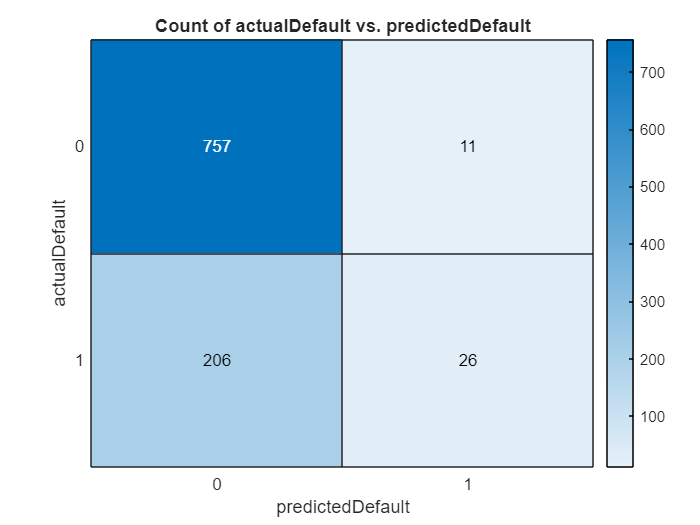

[trainedClassifier, validationAccuracy] = trainClassifier(data1_train);
predictedDefault = trainedClassifier.predictFcn(data2_test);
actualDefault = data2_test.default;
T = table(predictedDefault,actualDefault);
heatmap(T,'predictedDefault','actualDefault');

accuracy_test = sum(actualDefault == predictedDefault)/numel(predictedDefault)*100

accuracy_test = 78.3000